# OpenRocket Data Analysis

Nathanael Jenkins, 22.01.2021

ICLR Altitude Record Team

clear
%USER DEFINED VARIABLES

%Export all data from OpenRocket
filename = ['SAMPLE_DATA.csv'];

%Rocket Name
name = 'SAMPLE';

%Body radius in mm
bodyRadius = double(46);

%Leading edge sweep (º)
delta = 30.252;

%Distance from nose to fins (m)
X = 0.777;

% Rocket length (m)
lTotal = 0.772;

% Launch rail length (m)
lRail = 3.000;

% Ejection delay (s)
eject = 14.000;

%READ DATA
rawTable = readtable(filename, 'VariableNamingRule', 'preserve');

%EXTRACT DATA
Time = rmmissing((table2array(rawTable(:, 1))));
alt = rmmissing((table2array(rawTable(:, 2))));
vVel = rmmissing((table2array(rawTable(:, 3))));
vAccel = rmmissing((table2array(rawTable(:, 4))));
tVel = rmmissing((table2array(rawTable(:, 5))));
tAccel = rmmissing((table2array(rawTable(:, 6))));
east = rmmissing((table2array(rawTable(:, 7))));
north = rmmissing((table2array(rawTable(:, 8))));
latdist = rmmissing((table2array(rawTable(:, 9))));
latdir = rmmissing((table2array(rawTable(:, 10))));
lVel = rmmissing((table2array(rawTable(:, 11))));
lAccel = rmmissing((table2array(rawTable(:, 12))));
lat = rmmissing((table2array(rawTable(:, 13))));
long = rmmissing((table2array(rawTable(:, 14))));
grav = rmmissing((table2array(rawTable(:, 15))));
alpha = rmmissing((table2array(rawTable(:, 16))));
rollRate = rmmissing((table2array(rawTable(:, 1))));
pitchRate = rmmissing((table2array(rawTable(:, 18))));
yawRate = rmmissing((table2array(rawTable(:, 19))));
mass = rmmissing((table2array(rawTable(:, 20))));
propMass = rmmissing((table2array(rawTable(:, 21))));
burn= propMass./(max(propMass));
cp = ((table2array(rawTable(:, 24))));
cp = special(cp, Time);
cg = ((table2array(rawTable(:, 25))));
cg = special(cg, Time);
stability = ((table2array(rawTable(:, 26))));
stability = special(stability, Time);
M = rmmissing((table2array(rawTable(:, 27))));
Re = rmmissing((table2array(rawTable(:, 28))));
thrust = rmmissing((table2array(rawTable(:, 29))));
drag = rmmissing((table2array(rawTable(:, 30))));
%N.B. some data columns are not currently used

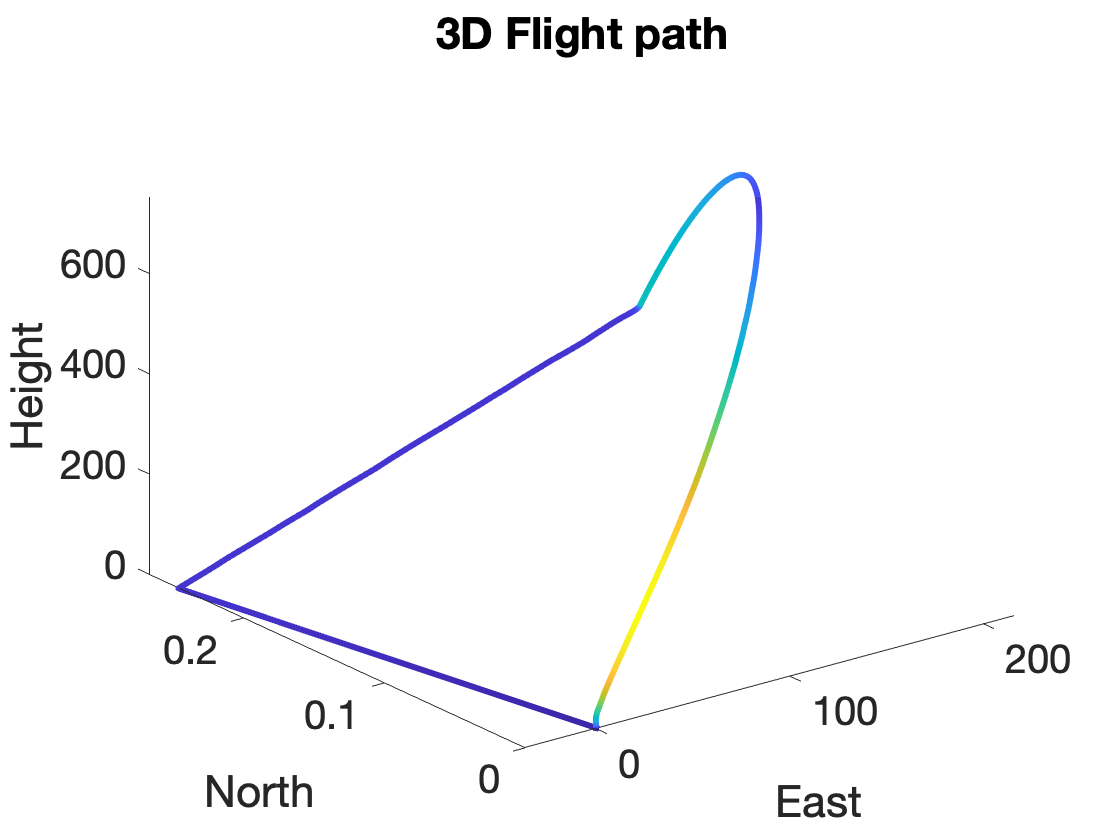

%PLOTS

%3D flight profile
figure(1)
fill3(east, north, alt, tVel, 'EdgeColor', 'interp', 'LineWidth', 3, 'FaceColor', 'none')
title('3D Flight path')
xlabel('East')
ylabel('North')
zlabel('Height')

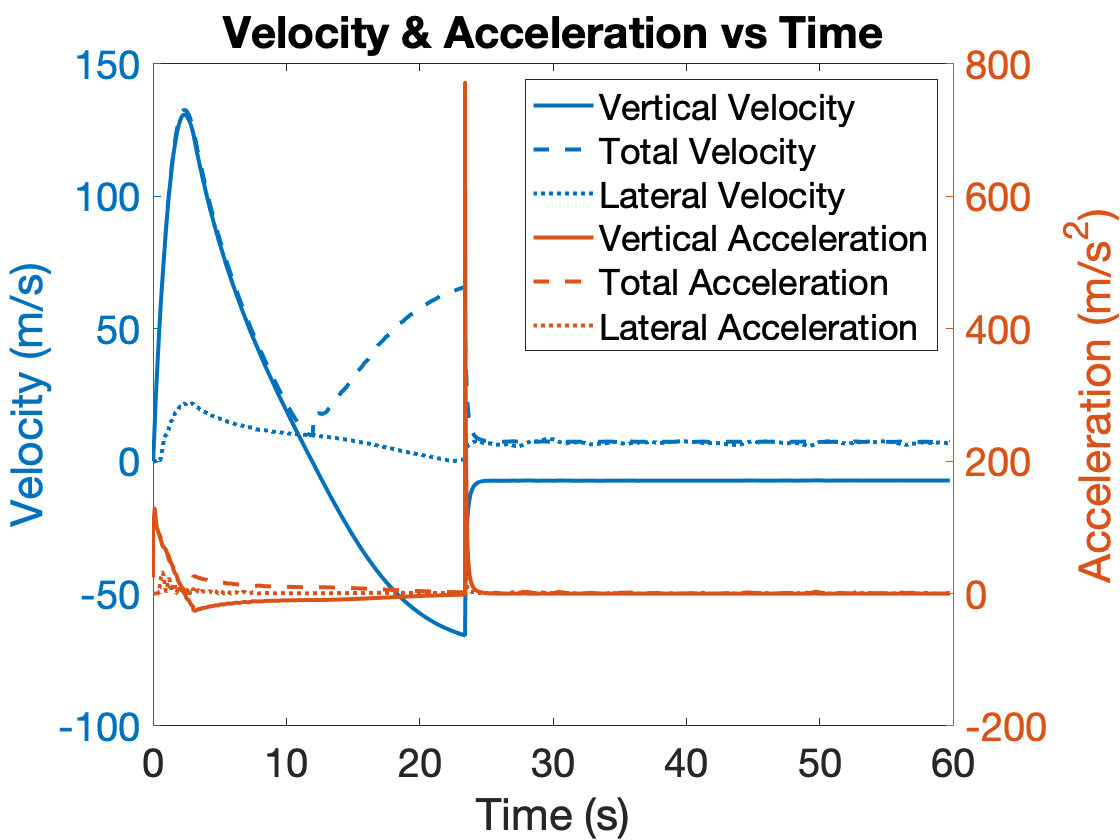


%Velocities
figure(3)
hold on
yyaxis left
ylabel('Velocity (m/s)')
plot(Time, vVel, Time, tVel, Time, lVel, 'Linewidth', 2)
yyaxis right
ylabel('Acceleration (m/s^2)')
plot(Time, vAccel, Time, tAccel, Time, lAccel, 'Linewidth', 2)
legend ('Vertical Velocity', 'Total Velocity', 'Lateral Velocity', 'Vertical Acceleration', 'Total Acceleration', 'Lateral Acceleration')
title('Velocity & Acceleration vs Time')
xlabel('Time (s)')
box on
hold off

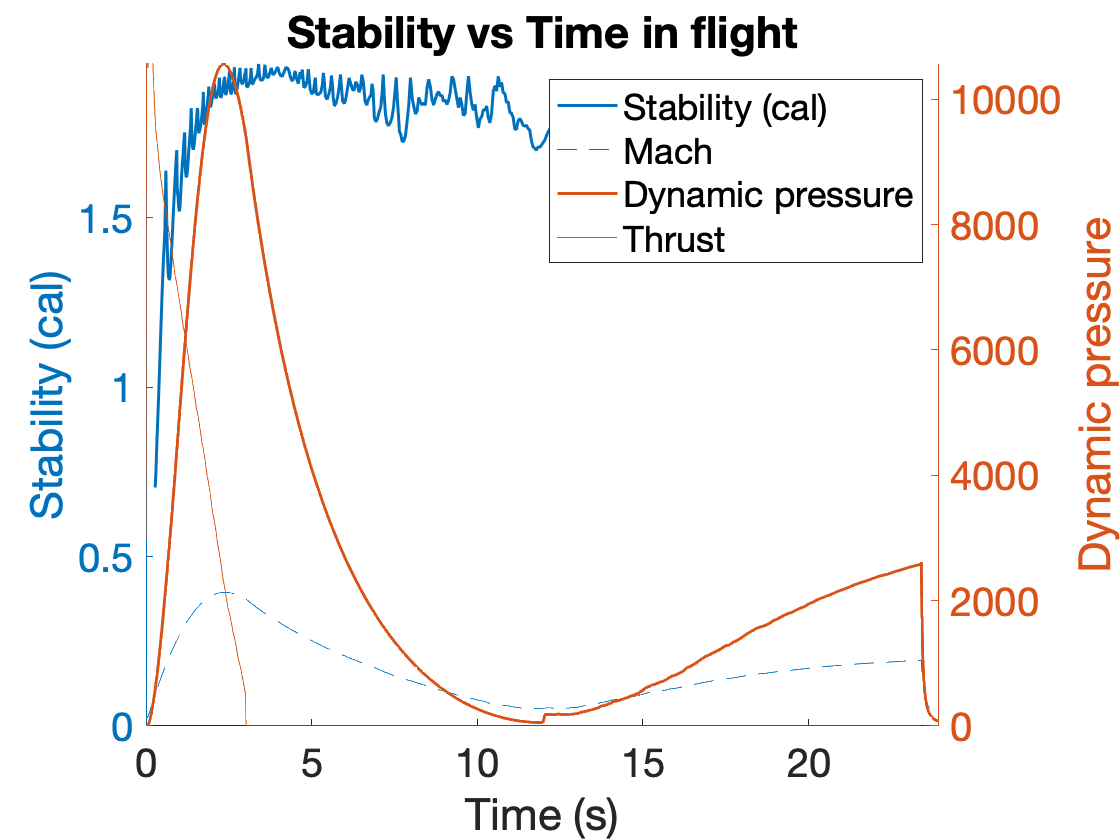


%Stability
for i=1:length(tVel)
    [~, ~, ~, rho_var(i, 1)] = atmosisa(alt(i));
end
Pd = 0.5.*rho_var.*tVel.*tVel;
figure
hold on
yyaxis left
plot(Time(stability>0), stability(stability>0), '-', 'Linewidth', 1.5)
plot(Time, M)
ylabel('Stability (cal)')
xlim([0 (0.4*max(Time))])
ylim([0 max(stability)])
yyaxis right
plot(Time, Pd, '-', 'Linewidth', 1.5)
ylim([0 max(Pd)])
plot(Time, thrust*100, '-')
ylabel('Dynamic pressure')
title('Stability vs Time in flight')
xlabel('Time (s)')
legend('Stability (cal)', 'Mach', 'Dynamic pressure', 'Thrust')
hold off

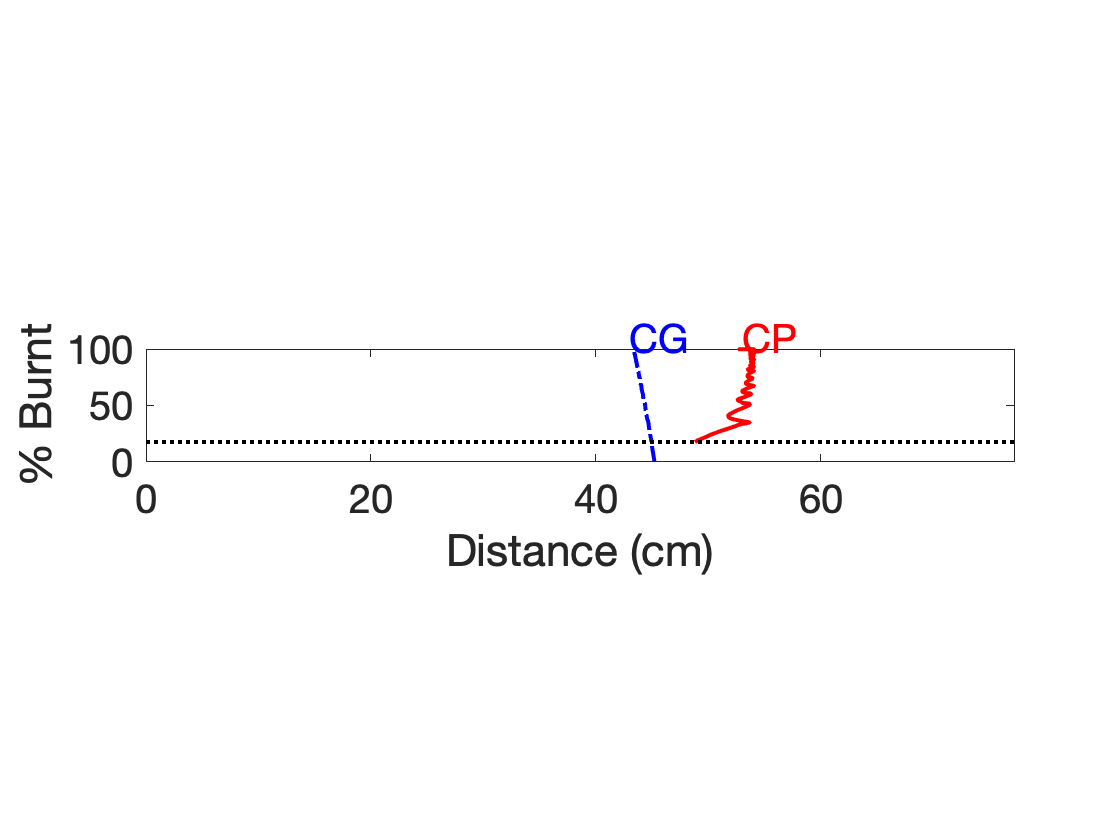

%GRAPHICS

% Stability graphic
figure(4)
% subplot(2, 1, 1);
% imshow(Image)
% % NEEDS ADJUSTING FOR EACH IMAGE - BETTER SOLUTION COMING SOON
% temp=1.3;
% xlim([-1200*temp 6000*temp])
% title(name)
% % hold on
% subplot(2, 1, 2)
plot(cp(cp~=0), 100-burn(cp~=0).*100, 'r-', 'lineWidth', 2)
hold on
daspect([0.1 1 1])
plot(cg(cg~=0), 100-burn(cg~=0).*100, 'b-.', 'lineWidth', 2)
temp = (1-max(burn(cp~=0)))*100;
plot([0 lTotal*100], [temp temp], 'k:', 'lineWidth', 2)
% text(0.75*lTotal*100, temp*1.4, 'Launch rod clearance')
xlim([0 lTotal*100])
ylim([0 100])
% title('Variation in c.p. and c.g. positions in flight')
xlabel('Distance (cm)', 'FontSize', 20)
ylabel('% Burnt', 'FontSize', 20)
% legend('cp', 'cg')
text(53, 110, 'CP', 'color', 'red', 'FontSize', 20)
text(43, 110, 'CG', 'color', 'blue', 'FontSize', 20)
set(0,'defaultAxesFontSize', 20);
hold off

% saveas(gcf, "SAMPLE.jpg")

%HEATING CALCULATIONS - UNDER REVIEW

% %Nose
% [V, I] = (max(tVel));
% V = double(V);
% Ma=M(I);
% [empty1, empty2, empty3, rho] = atmosisa(alt(I));
% e=double(0.92);
% to=double((1+0.2*Ma^2)*274.375);
% tol=1.0;
% i=0;
% N = double(((bodyRadius/1000)^(-0.5))*((1.83)*10.0^(-8)));
% Z = double(((rho^0.5)*(V^3))/((e)*((5.67)*10.0^(-12))));
% C1 = 0;
% 
% while (tol > 10.0^(-12))
%     %Computes a new value for constant C
%     C2 = ((((-C1/N)+1)*to)^4)/Z;
%     %Calculates tolerance based on change in estimated temperature over each iteration
%     tol = abs(((Z*C2)^0.25)-((Z*C1)^0.25));
%     %Re-assigns calculated value of C to 'old' value
%     C1 = C2;
%     %Increase iteration count by 1
%     i = i+1;
% end
% Tw = ((Z*C1)^0.25);
% 
% %Fin leading edge
% phi1 = 0;
% phi2 = 89;
% qo = C1*(rho^0.5)*(V^3);
% C1 = (2.53*(10^(-9)))*((cosd(phi1))^0.5)*(sind(phi1))*(X^(-0.5))*(1-(Tw/to));
% qfp = C1*rho^0.5*V^3.2;
% qle = sqrt(0.5*qo^2*cosd(delta)^2+qfp^2*sind(delta)^2);
% Tle1 = (qle/(e*((5.67)*10.0^(-12))))^0.25;
% 
% C1 = (2.53*(10^(-9)))*((cosd(phi2))^0.5)*(sind(phi2))*(X^(-0.5))*(1-(Tw/to));
% qfp = C1*rho^0.5*V^3.2;
% qle = sqrt(0.5*qo^2*cosd(delta)^2+qfp^2*sind(delta)^2);
% Tle2 = (qle/(e*((5.67)*10.0^(-12))))^0.25;

%SUMMARY
temp = stability(stability>0);
[Q, I] = max(Pd);
disp('                --SUMMARY OF DATA--')

                --SUMMARY OF DATA--


disp(name)

SAMPLE


disp('--------------------------------------------------')

--------------------------------------------------


disp(['           STABILITY AT LAUNCH: ' num2str(temp(1)), ' cal'])

           STABILITY AT LAUNCH: 0.70421 cal


disp(['                   LAUNCH MASS: ' num2str(mass(1)), ' g'])

                   LAUNCH MASS: 878.78 g


disp(['              MAXIMUM VELOCITY: ', num2str(max(vVel)), ' m/s'])

              MAXIMUM VELOCITY: 130.85 m/s


disp(['          MAXIMUM ACCELERATION: ', num2str(max(vAccel)), ' m/s^2'])

          MAXIMUM ACCELERATION: 772.49 m/s^2


disp(['                        APOGEE: ', num2str(max(alt)), ' m'])

                        APOGEE: 752.69 m


disp(['                    FINAL MASS: ', num2str(mass(length(mass))), ' g'])

                    FINAL MASS: 782.14 g


disp(['           GROUND HIT VELOCITY: ', num2str(tVel(end)), ' m/s'])

           GROUND HIT VELOCITY: 7.332 m/s


disp(['                         MAX Q: ', num2str(Time(I)), ' s'])

                         MAX Q: 2.3307 s


disp('--------------------------------------------------')

--------------------------------------------------


% disp (['Maximum stagnation temperature: ', num2str(to-273.15), ' ºc'])
% disp (['              Nose temperature: ', num2str(Tw-273.15), ' ºc'])
% disp (['  Min Leading Edge temperature: ', num2str(Tle1-273.15), ' ºc'])
% disp (['  Max Leading Edge temperature: ', num2str(Tle2-273.15), ' ºc'])
% disp ('-------------------------------------------------')
disp(' ')

disp(' ')

disp(' ')

disp(' ')

disp(' ')


% FLIGHT EVENTS
lrClear = find(alt>lRail, 1);
burnOut = find(thrust==0, 1);
landing = find(alt <= 0, 2);
[~, maxForce] = max(tAccel);
[~, app] = max(alt);

RodClear = Time(lrClear);
maxQ = Time(I);
burnOutTime = Time(burnOut);
apogeeTime = Time(app);
maxForceTime = Time(maxForce);
landingTime = Time(landing(end));
events = {"Rod clear", "Max Q", "Motor burn out", "Apogee", "Ejection charge", "Chute deployment", "Landing"; Time(lrClear), Time(I), Time(burnOut), Time(app), eject, Time(maxForce),  Time(landing(end))};
% At some point, add ordering in case of different order of events

if burnOut == 1
    warning('Motor burnout may be affected by poor thrust curve. Ensure thrust > 0 at T+00.000');
end
disp(['                  --FLIGHT EVENTS--'])

                  --FLIGHT EVENTS--


disp(name)

SAMPLE


disp('--------------------------------------------------')

--------------------------------------------------


disp(['                        LAUNCH: T+0.0000'])

                        LAUNCH: T+0.0000


disp(['         LAUNCH RAIL CLEARANCE: T+', num2str(RodClear)])

         LAUNCH RAIL CLEARANCE: T+0.24


disp(['                         MAX Q: T+', num2str(maxQ)])

                         MAX Q: T+2.3307


disp(['                 MOTOR BURNOUT: T+', num2str(burnOutTime)])

                 MOTOR BURNOUT: T+3.0308


disp(['                        APOGEE: T+', num2str(apogeeTime)])

                        APOGEE: T+11.933


disp(['               EJECTION CHARGE: T+', num2str(eject)])

               EJECTION CHARGE: T+14


disp(['              CHUTE DEPLOYMENT: T+', num2str(maxForceTime)])

              CHUTE DEPLOYMENT: T+23.404


disp(['                       LANDING: T+', num2str(landingTime)])

                       LANDING: T+59.767


disp('--------------------------------------------------')

--------------------------------------------------



save Flight_Events.mat events